# Estimation, Filtering and Detection

## Homework 1B: Forgetting methods

## Timur Uzakov

## MACROS

storeFigures = false; % set true if you want to save plots

## Problem 1:

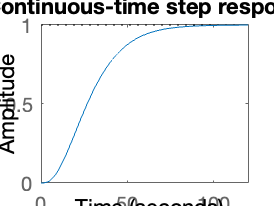

% Y(s) = 1/(1+s*tau)ˆ3*U(s)
% Find discrete time model
% Show dependancy of a(d) and b(d) parameters on
% time constant tau
Ts = 1;
% Assume ARX model structure

% Plan:
% Create transfer function
% Convert continuous state space to discrete
% implement ARX model
% show dependency of a and b on tau


time = 1000;
T = 0:Ts:time-1;
T_all = 0:Ts:3*time-1;
% Solution
% Continuous-time system
tau = 10;
sys = tf(1,[tau^3 3*tau^2 3*tau 1]);
figure(1);
step(sys);
title("Continuous-time step response");

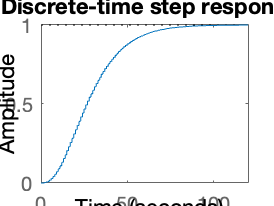


% Discrete-time system
dsys = c2d(sys,Ts,'tustin'); % using bilinear approximation 
[response,t] = step(dsys,T);
figure(2);
step(dsys);
title("Discrete-time step response");

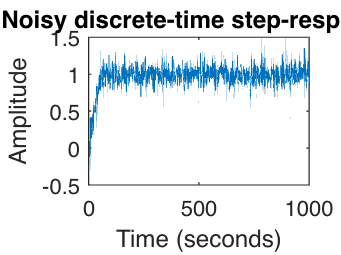


% Noisy discrete-time system
variance =0.01;
noisevec = sqrt(variance)*randn(time,1);
y = response + noisevec;
figure(3);
plot(t,y);
title("Noisy discrete-time step-response");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 2:

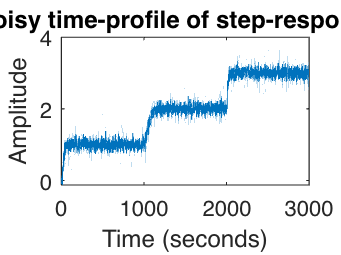


% Consider time profile

% Plan:
% Plot model from 0 to 3000 with constant tau1
% Implement if statements that change tau for each of the periods
% Plot the profile
% Do not forget the noise

% Solution
input = ones(time,1);       % step signal
time_profile = computeTimeProfile(input,Ts);
figure(4);
plot(T_all',time_profile);  % time-profile
title("Noisy time-profile of step-responses");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 3:

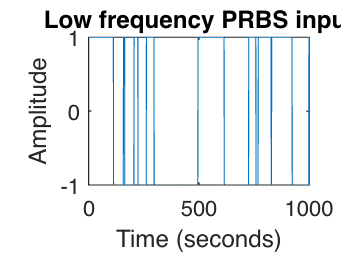

% Generate input-output data
% Use excitation signals
% Pseudo-binary sequence with 
% low frequency, white noise, high frequency
% Select the signal

% Plan:
% Find implementation of pseudo-binary signals from class materials
% Implement 3 signals 
% Generate input data and simulate the system
% Plot graphs
% Justify selection


% input sequence - low frequency input
p_switch = 0.01;
UU_low = createSignal(p_switch,time);
figure(5);
plot(T',UU_low);
title("Low frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

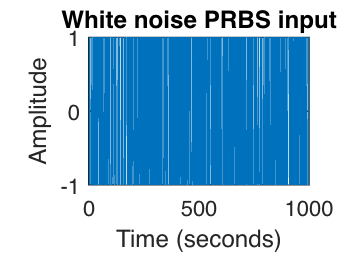


% input sequence - white noise input
p_switch = 0.5; 
UU_white = createSignal(p_switch,time);
plot(T',UU_white);
title("White noise PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

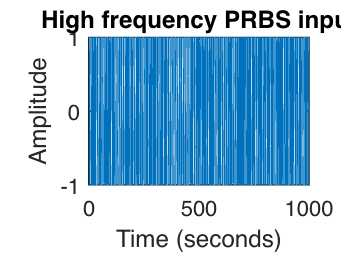


% input sequence - high frequency input 
p_switch = 0.9; 
UU_high = createSignal(p_switch,time);
plot(T',UU_high);
title("High frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)"); 

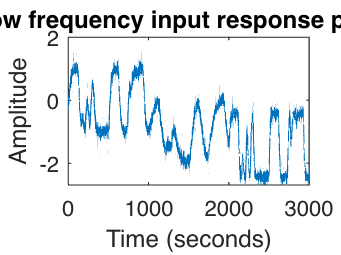


input = UU_low;      % low-frequency signal
time_profile_low = computeTimeProfile(input,Ts);
figure(6);
plot(T_all',time_profile_low); 
title("Low frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

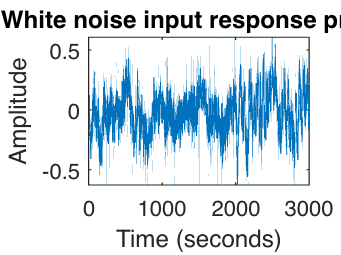


input = UU_white;      % white-noise signal
time_profile_white = computeTimeProfile(input,Ts);
figure(7);
plot(T_all',time_profile_white);
title("White noise input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

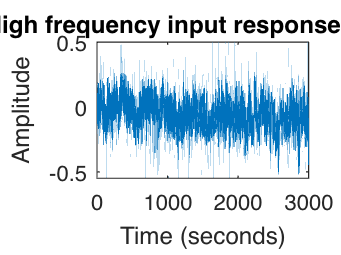


input = UU_high;      % high-frequency signal
time_profile_high = computeTimeProfile(input,Ts);
figure(8);
plot(T_all',time_profile_high); 
title("High frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");


% Conclusion
% Because white-noise and high-frequency input signal
% do not show clearly dynamical changes
% the low-frequency input signal has been chosen

UU = UU_low;

% Problem 4:
% Perform parameters tracking using different forgetting methods
% For each of the signals obtained before

% Linear
% Exponential
% Time Varying exponential
% Restricted
% Use of prior information


% With each of the signals obtained before

% Plan
% Make parameter tracking function for each of the methods

% Problem 5
% Conclusion
% Lessons learned

% Plan
% Describe how each forgetting method affects results of parameter
% estimation
% Describe how does each excitation signal has influence on results of
% parameter estimation


## Additional tools

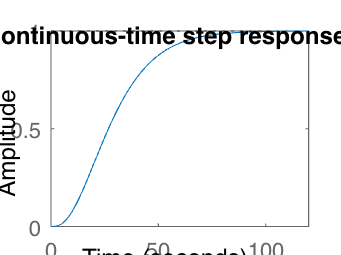

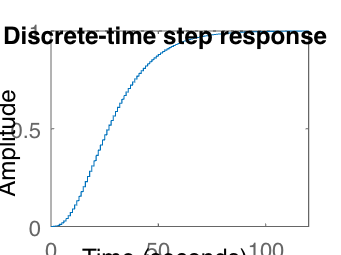

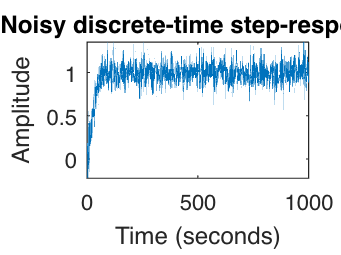

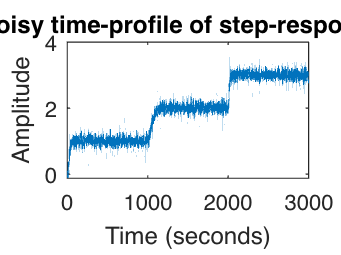

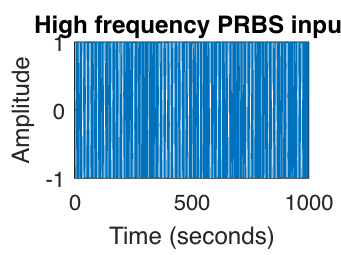

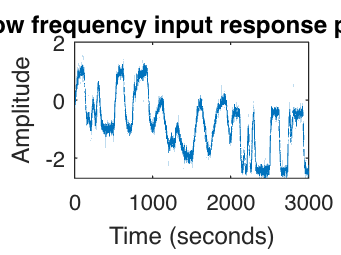

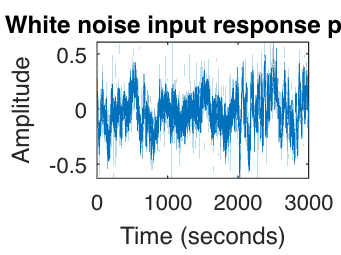

% Storing figures
if storeFigures
    for i=1:8
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end